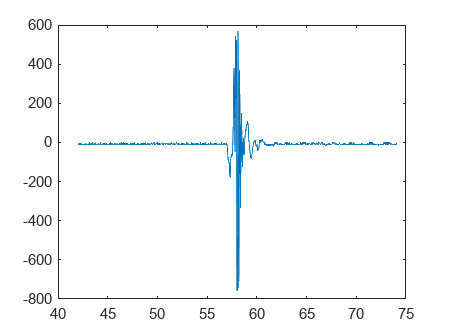

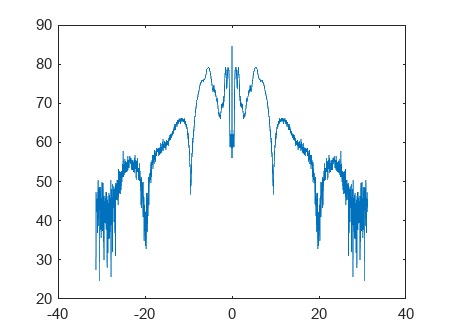

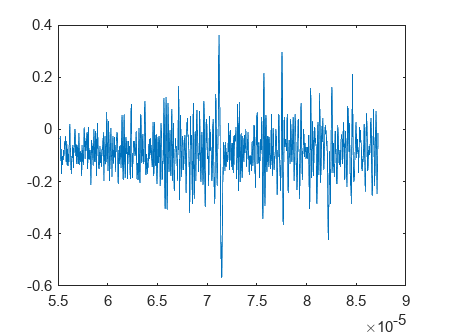

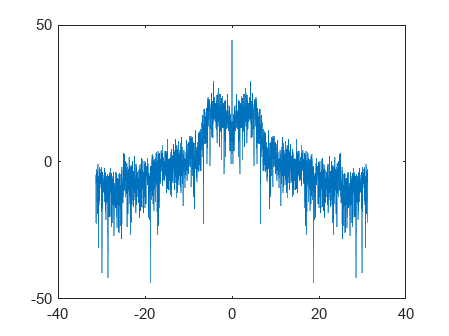

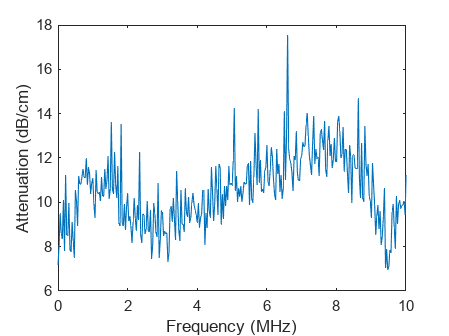

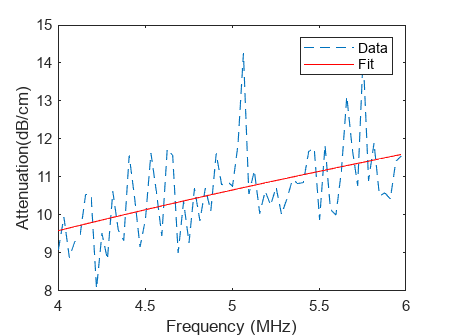

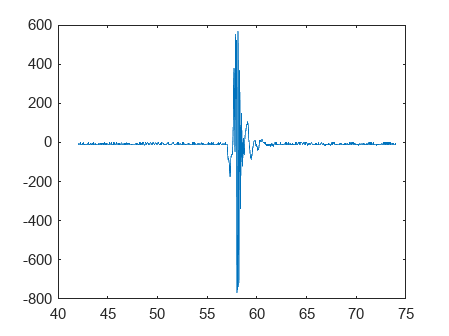

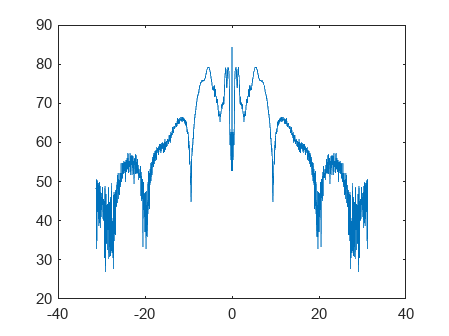

clear
%  x1 data_plexi = [22 23 24 25], data_corn = [10 11 12 13]
%  x3 data_plexi = [43 44 45 46], data_corn = [26 27 28 29]
%  x5 data_plexi = [59 60 61 62], data_corn = [47 48 49 50]
%  x10 data_plexi = [75 76 77 78], data_corn = [63 64 65 66]
addpath('C:\Users\User\Documents\K-wave\00PESCERA\02-10');
plexi=[16 17 18];
corn=[6 7 8 9];

[PlexiGrid, CornGrid] = ndgrid(plexi, corn);
combinations = [PlexiGrid(:), CornGrid(:)];

for i=1:length(combinations)

    data_plexi = readmatrix(sprintf('TEK000%d.CSV', combinations(i, 1)),"Range", "A17:B20016");
    N = 2000; % # samples recorded
    time_vec = data_plexi(:,1); %[s]
    volt_vec = data_plexi(:,2); %[V]
    PRF = 30*128; %[HZ]
    Fs = 1/((time_vec(end)-time_vec(1))/N); % sampling frequency [samples/s]
    figure,
    plot (time_vec*1e6,volt_vec)
    [fft_ref,Hz_ref,w_ref]=fftxd(volt_vec,Fs,"Ref signal");
    
%     fc_Hz=[4e6 6e6];
%      n=200;
%     [b,Wn]=fir1xd(n,fc_Hz,Fs,"HIGH",hanning(n+1));
%      fft_ref=filter(b,1,fft_ref);
%      figure,
%     plot(Hz_ref*1e-6,fft_ref),% xlim([0 10])

    power_spectrum = (abs(fft_ref) .^ 2);
    ps_db_plexi= 10*log10(power_spectrum);
    figure
    plot(Hz_ref*1e-6,ps_db_plexi)
    
    rho= 1.05; 
    c=1470.5;
%     c=872;
    rhor= 1;  % reference water
    cr=1480.81;
    D1= 2*(rhor*cr)/((rhor*cr)+(rho*c)); % Tcw
    D2= 2*(rho*c)/((rhor*cr)+(rho*c)); % Twc
    TL = (D1*D2)^2; % Transmission_loss
    % TL=1;
    data_corn = readmatrix(sprintf('TEK0000%d.CSV', combinations(i, 2)),"Range", "A17:B20016");
    N = 2000; % # samples recorded
    time_vec = data_corn(:,1); %[s]
    volt_vec = data_corn(:,2); %[V]
    PRF = 30*128; %[HZ]
    Fs = 1/((time_vec(end)-time_vec(1))/N); % sampling frequency [samples/s]
    figure,
    plot (time_vec,volt_vec)
    [fft_ref,Hz_ref,w_ref]=fftxd(volt_vec,Fs,"Ref signal");

%     fc_Hz=[4e6 6e6];
%      n=200;
%     [b,Wn]=fir1xd(n,fc_Hz,Fs,"HIGH",hanning(n+1));
%      fft_ref=filter(b,1,fft_ref);
%      figure,
%     plot(Hz_ref*1e-6,fft_ref),% xlim([0 10])

    power_spectrum = (abs(fft_ref) .^ 2);

    ps_db_corn= 10*log10(power_spectrum/TL);
%     fc_Hz=[3.5e6 6.5e6];
%      n=200;
%     [b,Wn]=fir1xd(n,fc_Hz,Fs,"HIGH",hanning(n+1));
%      ps_db_corn=filter(b,1,ps_db_corn);
%      figure,
%     plot(Hz_ref*1e-6,fft_ref),% xlim([0 10])

    figure,
    plot(Hz_ref*1e-6,ps_db_corn),% xlim([0 10])
    
     
    f= 5;
    d= 2.8;
    % d=4.6;
    
    figure; plot(Hz_ref*1e-6, (ps_db_plexi - ps_db_corn)/(2*d)); xlabel ("Frequency (MHz)"),xlim([0 10]), ylabel ("Attenuation (dB/cm)")
    
    att_new = (ps_db_plexi - ps_db_corn)/(2*d); 
    [~, idx1] = min(abs(Hz_ref*1e-6-2.25));
    [~, idx2] = min(abs(Hz_ref*1e-6-4.5));
    att_1 = att_new((idx1));
    att_2 = att_new((idx2));
    
    
    f_min = 4 * 1e6;
    f_max = 6 * 1e6;
    
    idx_min = find(Hz_ref >= f_min, 1, 'first');
    idx_max = find(Hz_ref <= f_max, 1, 'last');
    
    frequencies_range = Hz_ref(idx_min:idx_max) / 1e6;
    att_range = att_new(idx_min:idx_max);
    
    frequencies_range = frequencies_range(:);
    att_range = att_range(:);
    
    fit_func = fittype('alpha0 * f^gamma', 'independent', 'f', 'coefficients', {'alpha0', 'gamma'});
    
    [fit_result, gof] = fit(frequencies_range, att_range, fit_func);
    
    alpha0(i) = fit_result.alpha0;
    gamma(i) = fit_result.gamma;
    
%     disp(['alpha0: ', num2str(alpha0)]);
%     disp(['gamma: ', num2str(gamma)]);
    
    
    slope(i)= alpha0(i) * gamma(i)*f^(gamma(i)-1);
    
%     disp(['slope: ', num2str(slope)]);
    
    
    figure;
    plot(frequencies_range, att_range, '--');
    hold on;
    plot(frequencies_range, fit_result(frequencies_range), 'r-');
    xlabel('Frequency (MHz)');
    ylabel('Attenuation(dB/cm)');
    legend('Data', 'Fit');
    % title('Fit of alpha(f) = alpha0 * f^{gamma}');
    hold off;

end


% plot(Hz_ref*1e-6,Beta), xlim ([0 10])


function [X_k,Hz,w]=fftxd(x,fs,tex) %Function that automatically normalizes the Frequency domain in Hz and plots the DFT of the signal in the input.
    k=0:length(x)-1;
    k=k-floor(length(x)/2);
    Hz=k*fs/length(x);
    w=Hz*pi/(fs/2);
%    X_k=(fftshift(fft(x)));

    X_k=abs(fftshift(fft(x)));
   %  X_k=20*log10(abs(X_k));
     %X_k=X_k-max(X_k(:));
    
    % Limitar la frecuencia a 0 Hz y 15 MHz
    mask = Hz >= 0 & Hz <= 10e6;
    
%     figure,
%     plot(Hz(mask)/1e6, X_k(mask, 1)); % Convertir Hz a MHz
%     xlabel("Frequency (MHz)");
%     ylabel("Amplitude ");
%     title(tex);
%     xlim([0 15]); % Limitar el rango de frecuencia de 0 a 15 MHz
%     grid on;
end

function [b,Wn]=fir1xd(n,fc_Hz,fs,type,win)
    if length(fc_Hz)==1
       Wn=fc_Hz/(fs/2);
    else%%%this condition met when we need a bandpass filter
        Wn=[fc_Hz(1)/(fs/2),fc_Hz(2)/(fs/2)];
    end
    b=fir1(n,Wn,type,win); 
    %[b_k,Hz_b]=fftxd(b,fs,"Frequency Spectrum of FIR, in Hz");
%     figure,
%     freqz(b,1)
end
